# YOLOv4 Model to Detect Parking Signs 

In this script, we'll use the YOLOv4 object detector with two detection heads, or "tiny-yolo" to detect parking signs.

## Importing ground truth data object and converting to datastores

load parkingTrainGT.mat gTruth

Converting ground truth data to an `imageDatastore` and `boxLabelDatastore` 

[imds,blds] = objectDetectorTrainingData(gTruth);
nFiles = length(imds.Files)

nFiles = 400

classes = categories(blds.LabelData{1,2})

classes = 3×1 cell array
    {'Accessible'}
    {'Charger'   }
    {'EV'        }


Combining the `imageDatastore` and `boxLabelDatastore` datastores

data = combine(imds,blds);

## Estimating anchor boxes

Since YOLO v4 requires anchor boxes, we need to estimate them. The workflow will be to evaluate different numbers of anchor boxes using the intersection over union (IoU) of the anchor boxes with the ground truth as the evaluation metric. The first step is to choose a maximum number of anchors to evaluate. Here, we start with 24: 

maxAnchors = 24; 

Then, we will initialize variables to store results for all iterations. Since mean IoU will be a scalar at each iteration, we will use a vector of zeros. Each set of anchor boxes will be a matrix, so each iteration will be stored in an element of a cell array. 

meanIoU = zeros(maxAnchors, 1);
anchorBoxes = cell(maxAnchors, 1);

Estimating the anchor boxes and mean IoU over a range of 1 to `maxAnchors`.

for idx = 1:maxAnchors
    [anchorBoxes{idx}, meanIoU(idx)] = estimateAnchorBoxes(data, idx);
end

**Visualizing the results**

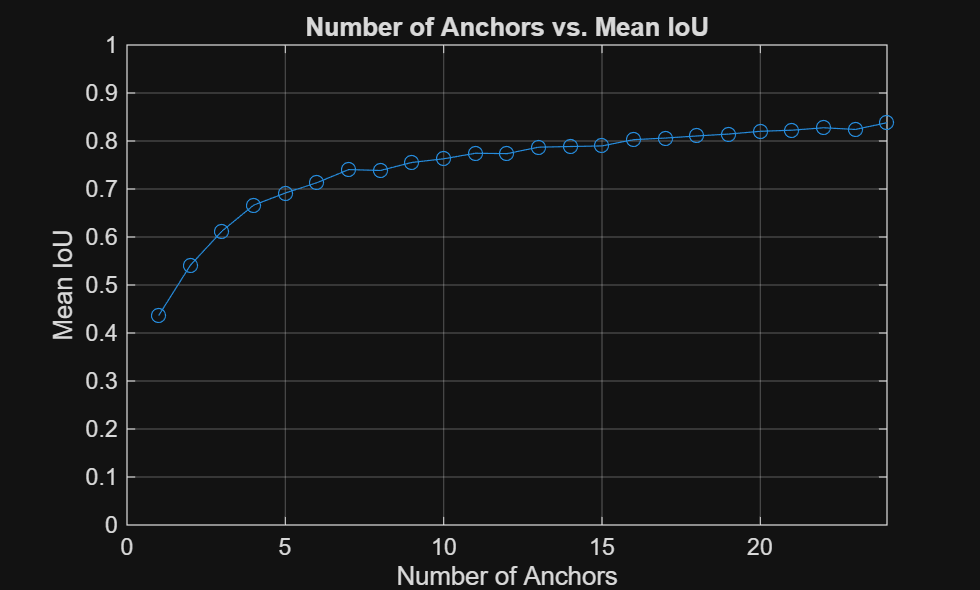

plot(1:maxAnchors, meanIoU, "-o")
axis([0,maxAnchors,0,1])
grid
xlabel("Number of Anchors")
ylabel("Mean IoU")
title("Number of Anchors vs. Mean IoU")

## Splitting the data into training and validation sets

Shuffling the datastore to randomize the files before making the training validation split.

data = shuffle(data);

Selecting a fraction of files to use for training and calculate the number of training files. Here, we keep 80% of the training data as training and use 20% for validation. 

trainingFraction = 0.8;
numTraining = floor(nFiles*trainingFraction);

Finally, using the `subset` function to split the data into training and validation sets.

trainingData = subset(data, 1:numTraining);
validationData = subset(data, (numTraining+1):nFiles);

## Building a detector 

Now we will build a detector to train. In this case, a YOLOv4 object detector. Based on the analysis above, it looks like 20 anchor boxes is a good initial number to try. 

anchors = anchorBoxes{20};

Now, we will sort the anchor boxes by area and assign them to the detection heads appropriately based their source depth in the backbone network. To do this, we will calculate the area of the anchors and then sort them by size. 

anchorArea = anchors(:,1).*anchors(:,2);
[~, idx] = sort(anchorArea);
anchors = anchors(idx, :);

In this example, there are two detection heads for the tiny-yolo network. 

trainingAnchors = cell(2, 1);
trainingAnchors{1} = anchors(1:6,:);
trainingAnchors{2} = anchors(7:12,:);

Now we will build the detector object. 

- The first input here specifies the name of the pre-trained network, in this case the "tiny" backbone (small version of Darknet 53). 

- The second input is the class names obtained earlier from the `boxLabelDatastore`.

- The third input is the sorted anchor boxes. 

detector = yolov4ObjectDetector("tiny-yolov4-coco",classes,trainingAnchors);

## Setting up training options and training the detector

Now, we will set the training options for the optimization algorithm to use and train our model.

*************************************************************************
Training a YOLO v4 Object Detector for the following object classes:

* Accessible
* Charger
* EV

Starting parallel pool (parpool) using the 'Processes' profile ...
Connected to parallel pool with 6 workers.
 
    Epoch    Iteration    TimeElapsed    LearnRate    TrainingLoss    ValidationLoss
    _____    _________    ___________    _________    ____________    ______________
      1          1         00:01:21        0.001         4637.5           4020.5    
      1          5         00:03:52        0.001         2281.6           1866.3    
      2         10         00:05:31        0.001         950.75           880.6     
      3         15         00:07:07        0.001         528.12           492.69    
 

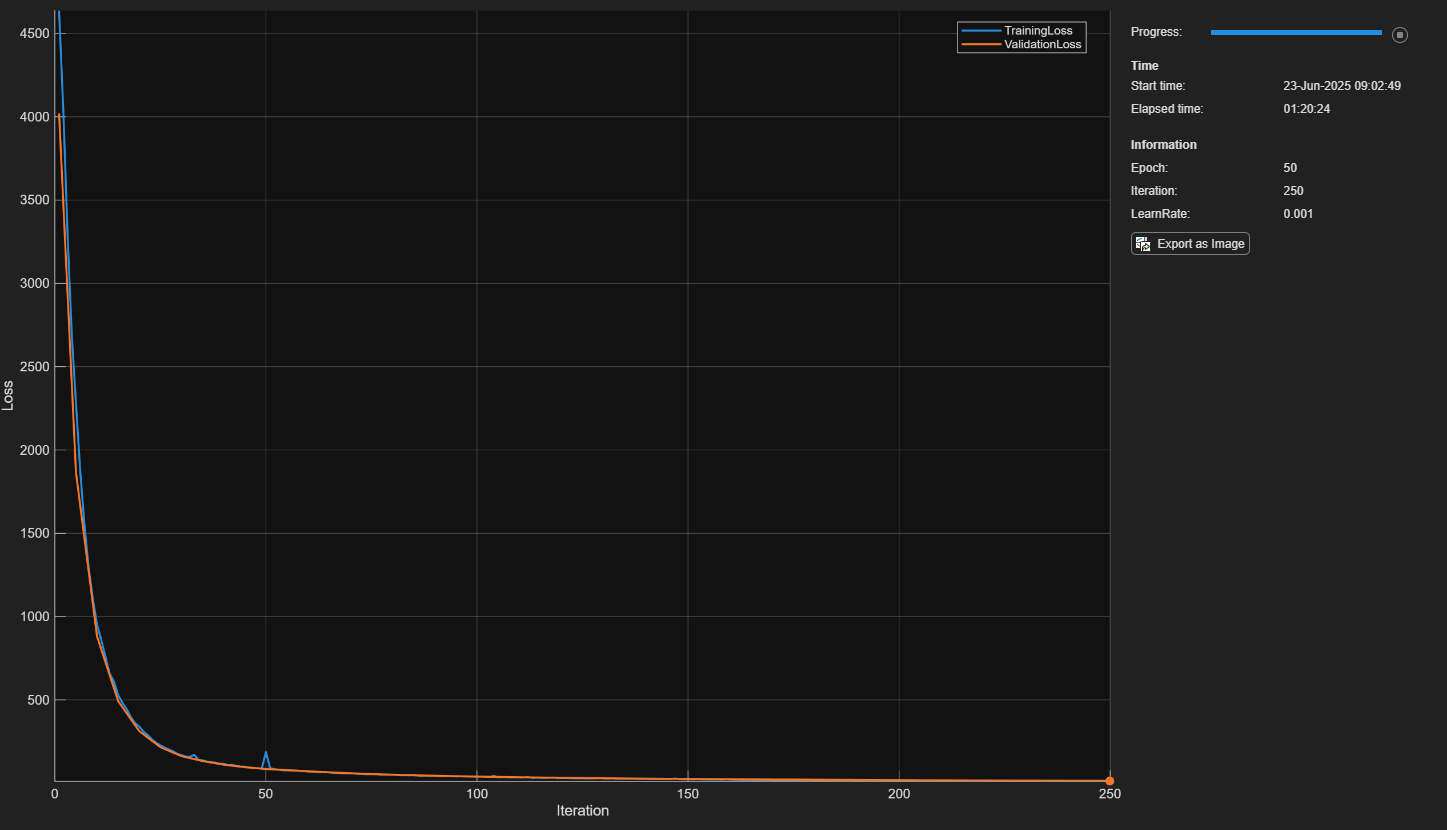

     50         250        01:20:12        0.001         11.641           14.327    

*************************************************************************
Detector training complete.
*************************************************************************



options = trainingOptions("adam",...
    GradientDecayFactor=0.9,...
    SquaredGradientDecayFactor=0.999,...
    InitialLearnRate=0.001,...
    LearnRateSchedule="none",...
    MiniBatchSize=64,...
    L2Regularization=0.001,... 
    MaxEpochs=50,... 
    BatchNormalizationStatistics="moving",...
    DispatchInBackground=true,...
    ResetInputNormalization=false,...
    Shuffle="every-epoch",...
    VerboseFrequency=10,...
    Plots = "training-progress",...
    ValidationData=validationData,...
    ValidationFrequency=5,...
    OutputNetwork="best-validation-loss");

% Training the model
[detector, info] = trainYOLOv4ObjectDetector(trainingData, detector, options);

## Saving the trained model results

save('trained_yolov4_detector.mat', 'detector');